## Accuracy, Latency, and Lick Rate Analysis for Andrew Luskin's Head-Fixed Go/No-Go Task

Code written by Zach Gershon, Genelle Rankin, and Andrew Luskin

clear all
close all

filename = 'M11_C249376_Date_10302023_DNMS_gonogo_Data_with_punishment.mat';
load(filename)
mousename = 'C249376_M11_10302023';

### Set Up Behavior Table

varnames = {'Time', 'New Trial', 'Trial Start Tone', 'Go Tone', 'No-Go Tone', 'Decision Start Point', 'Correct Decision', 'Incorrect Decision', 'Lickport Readout', 'Water Delivery', 'Trial Count', 'Go Trial Count', 'No-Go  Trial Count'};

behavior = table(exper.M(:,1),exper.M(:,6),exper.M(:,3),exper.M(:,4),exper.M(:,5),exper.M(:,14),exper.M(:,12),exper.M(:,13),exper.M(:,15), exper.M(:,9), exper.M(:,11), exper.M(:,18),exper.M(:,19));
behavior = renamevars(behavior,["Var1","Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13"],varnames);

%% Calculate and Add Lick Rate
lickrate=[];
count=0;
% secs = numel(behavior{:,"Time"})/behavior{end,"Time"};
for a=find(behavior{:,"Time"}>1,1,'first'):numel(behavior{:,"Time"})
    count=count+1;
    b=find(behavior{:,"Time"}<behavior{a,"Time"}-1,1,'last');
    lickrate(a,1)=sum(behavior{b:a,"Lickport Readout"})/(behavior{a,"Time"}-behavior{b,"Time"});
end
varname = {'Lick Rate'};
lickrate=table(lickrate);
behavior(:,end+1)=lickrate;
behavior = renamevars(behavior,"Var14",'Lick Rate');

### Create Containers for Final Data

gocorrect = cell(33,5);
goincorrect = cell(33,5);
nogocorrect = cell(33,5);
nogoincorrect = cell(33,5);
mixedsignalcorrect = cell(33,5);
mixedsignalincorrect = cell(33,5);
latencies_correct = cell(33,5);
latencies_delayed = cell(33,5);
latencies_all = cell(33,5);
d = cell(33,5);

f0count = 0;
f1count = 0;
f2count = 0;
f3count = 0;
f4count = 0;


### Identify Trial Start, Go/No-Go Tone Onset, and  Lick Row IDs and Times

trialidxs = find(behavior{:,"Trial Start Tone"}>0);

trialtimes = behavior{trialidxs,"Time"};

gocueidxs = find(behavior{:,"Go Tone"}>0);
gocuetimes = behavior{gocueidxs,"Time"};

nogocueidxs = find(behavior{:,"No-Go Tone"}>0);
nogocuetimes = behavior{nogocueidxs,"Time"};

lickidxs = find(behavior{:,"Lickport Readout"}>4);
licktimes = behavior{lickidxs,"Time"};

gocuecount = 0;
gocorrectcount = 0;
godelayedcount = 0;
goomitcount = 0;
goincorrectcount = 0;
correctlatencies = [];
delayedlatencies = [];
alllatencies = [];

nogocuecount = 0;
nogocorrectcount = 0;
nogoincorrectcount = 0;
responseperiod =2; %i added...

### Determine Accuracy and Latecy fro Go Trials

% for j = 1:numel(gocueidxs)
% 
%     gocuecount = gocuecount + 1;
% 
%     trialstart = gocueidxs(j)-trialidxs(trialidxs<gocueidxs(j));
%     trialstart = find(trialstart(:) == min(trialstart));
% 
%     if trialstart == numel(trialidxs)
%         nexttrial = numel(behavior{:,"New Trial"});
%     else
% %             nexttrial = find(behavior{gocueidxs(j):end,"New Trial"}>0,1,"first") + (gocueidxs(j) - 1);
%         nexttrial = trialidxs(trialstart+1);
%     end
% 
%     trialstart = trialidxs(trialstart);
% 
%     nextlick = find(behavior{gocueidxs(j):end,"Lickport Readout"}>4,1,"first") + (gocueidxs(j) - 1);
%     
%     if  ~isempty(nextlick)
% %             disp(behavior{nextlick,1})
% %             disp(behavior{gocueidxs(j),1})
% %             disp(behavior{nextlick,"Time"}-behavior{gocueidxs(j),"Time"})
%         latency  = behavior{nextlick,"Time"}-behavior{gocueidxs(j),"Time"};
%             
%         if latency < responseperiod %&& ~any(behavior{trialstart:gocueidxs(j),"Lickport Readout"}>4)
%             
%             gocorrectcount  = gocorrectcount + 1;
%             correctlatencies = [correctlatencies; latency];
%             alllatencies  = [alllatencies; latency];
% 
%         elseif ~isempty(nexttrial)
%             
%             if nextlick < nexttrial
% 
%                 godelayedcount = godelayedcount + 1;
%                 goincorrectcount = goincorrectcount + 1;
% 
%                 if latency <= 10
%                     delayedlatencies = [delayedlatencies; latency];
%                     alllatencies  = [alllatencies; latency];
%                 else
%                     delayedlatencies = [delayedlatencies; NaN];
%                     alllatencies  = [alllatencies; NaN];
%                 end
%                 
%             else
% 
%                 goomitcount = goomitcount + 1;
%                 goincorrectcount = goincorrectcount + 1;
% 
%             end
% 
%         else
%             
%             godelayedcount = godelayedcount + 1;
%             goincorrectcount = goincorrectcount + 1;
% 
%             if latency <= 10
%                 delayedlatencies = [delayedlatencies; latency];
%                 alllatencies  = [alllatencies; latency];
%             else
%                 delayedlatencies = [delayedlatencies; NaN];
%                 alllatencies  = [alllatencies; NaN];
%             end
% 
%         end
% 
%     else
% 
%         goomitcount = goomitcount + 1;
%         goincorrectcount = goincorrectcount + 1;
% 
%     end
% 
% end

### Determine Accuracy and Latency for No-Go Trials

% for j = 1:numel(nogocueidxs)
% 
%     nogocuecount = nogocuecount + 1;
% 
%     trialstart = nogocueidxs(j)-trialidxs(trialidxs<nogocueidxs(j));
%     trialstart = find(trialstart(:) == min(trialstart));
% 
%     if trialstart == numel(trialidxs)
%         nexttrial = numel(behavior{:,"New Trial"});
%     else
% %             nexttrial = find(behavior{nogocueidxs(j):end,"New Trial"}>0,1,"first") + (nogocueidxs(j) - 1);
%         nexttrial = trialidxs(trialstart+1);
%     end
% 
%     trialstart = trialidxs(trialstart);
% 
%     nextlick = find(behavior{nogocueidxs(j):end,"Lickport Readout"}>4,1,"first")  + (nogocueidxs(j) - 1);
%     
%     if  ~isempty(nextlick)
% 
%             if behavior{nextlick,"Time"}-behavior{nogocueidxs(j),"Time"} > responseperiod && ~any(behavior{trialstart:nogocueidxs(j),"Lickport Readout"}>4)
%                 
%                 nogocorrectcount  = nogocorrectcount + 1;
%             
%             else
%                 
%                 nogoincorrectcount = nogoincorrectcount + 1;
% 
%             end
% 
%     else
% 
%         nogocorrectcount = nogocorrectcount + 1;
%                     
%     end
% 
% end

### Calculate Correct/Incorrect Rates and Discrimination Index

% gocorrectrate = (gocorrectcount/gocuecount)*100;
% goincorrectrate = (goincorrectcount/gocuecount)*100;
% nogocorrectrate = (nogocorrectcount/nogocuecount)*100;
% nogoincorrectrate = (nogoincorrectcount/nogocuecount)*100;
% discrimination = (gocorrectcount-nogoincorrectcount)/gocuecount;

The mixedcorrectrate and mixedincorrectrate variables calculate a mouse's accuracy in responding to any tone, regardless of Go/No-Go association, essetially making the calculation for a generalized signal detection task.

% mixedcorrectrate = ((gocorrectcount + nogoincorrectcount)/(gocuecount + nogocuecount))*100;
% mixedincorrectrate = ((goincorrectcount + nogocorrectcount)/(gocuecount + nogocuecount))*100;

### Saving Data

% save(filename, "exper", "behavior","gocueidxs", "gocuetimes", "gocuecount", "gocorrectcount", "goincorrectcount", "godelayedcount", "goomitcount",...
%     "nogocueidxs", "nogocuetimes", "nogocuecount", "nogocorrectcount", "nogoincorrectcount", "correctlatencies", "delayedlatencies", "alllatencies",...
%     "trialidxs", "trialtimes", "lickidxs", "licktimes");



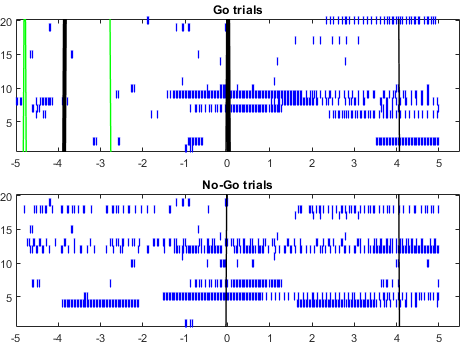

% trialidxs = find(behavior{:,"New Trial"}>0);
% trialtimes = behavior{lickidxs,"Time"};    

% gocueidxs = find(behavior{:,"Go Tone"}>0);
% gocuetimes = behavior{gocueidxs,"Time"};

deliveryidxs = find(behavior{:,"Correct Decision"}>0 | behavior{:,"Incorrect Decision"}>0);
deliverytimes = behavior{deliveryidxs,"Time"};
% 
% nogocueidxs = find(behavior{:,"No-Go Tone"}>0);
% nogocuetimes = behavior{nogocueidxs,"Time"};
% 
% lickidxs = find(behavior{:,"Lickport Readout"}>4);
% licktimes = behavior{lickidxs,"Time"};

if length(behavior{1,:})<14
    %% Calculate and Add Lick Rate
    lickrate=[];
    count=0;
    % secs = numel(behavior{:,"Time"})/behavior{end,"Time"};
    for a=find(behavior{:,"Time"}>1,1,'first'):numel(behavior{:,"Time"})
        count=count+1;
        b=find(behavior{:,"Time"}<behavior{a,"Time"}-1,1,'last');
        lickrate(a,1)=sum(behavior{b:a,"Lickport Readout"}*2)/(behavior{a,"Time"}-behavior{b,"Time"});
    end

    lickrate=table(lickrate,VariableNames={'Lick Rate'});
    
    behavior(:,end+1)=lickrate;
    
    behavior = renamevars(behavior,"Var14",'Lick Rate');
end

% triallength = {};
% for i = 1:numel(trialidxs)-1
%     triallength{i,1} = trialidxs(i):trialidxs(i+1);
% end
% triallength{numel(trialidxs),1} = trialidxs(numel(trialidxs)-1):trialidxs(numel(trialidxs));
% 
% % for i = 1:numel(triallength)
% %     triallength{i,2} = length(triallength{i,1});
% % end
% 
% gotrials = {};
% nogotrials = {};
% for i = 1:numel(triallength(:,1))
%     if any(behavior{triallength{i,1},"Go Tone"})
%         gotrials = [gotrials;triallength(i,1)];
%     elseif any(behavior{triallength{i,1},"No-Go Tone"})
%         nogotrials = [nogotrials;triallength(i,1)];
%     end
% end
% 
% % maxlength = max(cell2mat(triallength(:,2)));
% % 
% % for i = 1:numel(triallength(:,1))
% %     if length(triallength{i,1})<maxlength
% %         lengthdiff =  maxlength - length(triallength{i,1});
% %         triallength{i,1} = [triallength{i,1},NaN(1,lengthdiff)];
% %     end
% % end

new_trialidxs = find(behavior{:,"New Trial"}>0);
trialends = behavior{new_trialidxs,"Time"};
lick_yes=[];
for i = 1:numel(behavior{:,"Lickport Readout"})
    if behavior{:,"Lickport Readout"}(i) >=4;
        lick_yes(i,1)=1;
    else
        lick_yes(i,1)=0;
    end
end
lickidxs = find(behavior{:,"Lickport Readout"}>4);

lick_numbers=zeros(length(lick_yes),1);
for i = 1:numel(new_trialidxs)
    for b = 1:numel(lick_yes)
        if i == 1;
            if b <= new_trialidxs(i) && lick_yes(b)==1;
                lick_numbers(b,1)=i;
            end
        else
            if b <= new_trialidxs(i) && b > new_trialidxs(i-1);
                if lick_yes(b)==1;
                    lick_numbers(b,1)=i;
                end
            end
        end
        
    end
end

varname = {'Lick Trials'};
lick_numbers=table(lick_numbers);
behavior(:,end+1)=lick_numbers;
behavior = renamevars(behavior,"Var15",'Lick Trials');

secs = round(numel(behavior{:,"Time"})/behavior{end,"Time"});

no_idxs=find(behavior{:,"No-Go Tone"}>0);
no_trials = behavior{no_idxs,"Trial Count"};
go_idxs=find(behavior{:,"Go Tone"}>0);
go_trials = behavior{go_idxs,"Trial Count"};


gotrials = {};
for i = 1:numel(go_trials)
    if deliveryidxs(go_trials(i))+(5*secs)< numel(behavior{:,"Time"})
        gotrials{i,1} = deliveryidxs(go_trials(i))-(5*secs):deliveryidxs(go_trials(i))+(5*secs);
%         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
%         trialend = find(behavior{:,"Time"}>=gocuetimes(i)+10,1,"first");
%         gotrials{i,1} = trialstart:trialend;
    else
        gotrials{i,1} = deliveryidxs(i)-(7*secs):numel(behavior{:,"Time"});
        lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
        gotrials{i,1} = [gotrials{i,1},NaN(1,lengthdiff)];
%         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
%         trialend = numel(behavior{:,"Time"});
%         gotrials{i,1} = trialstart:trialend;
    end
end

notrials = {};
for i = 1:numel(no_trials)
    if deliveryidxs(no_trials(i))+(5*secs)< numel(behavior{:,"Time"})
        notrials{i,1} = deliveryidxs(no_trials(i))-(5*secs):deliveryidxs(no_trials(i))+(5*secs);
%         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
%         trialend = find(behavior{:,"Time"}>=gocuetimes(i)+10,1,"first");
%         gotrials{i,1} = trialstart:trialend;
    else
      %  gotrials{i,1} = deliveryidxs(i)-(7*secs):numel(behavior{:,"Time"});
       % lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
        %gotrials{i,1} = [gotrials{i,1},NaN(1,lengthdiff)];
%         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
%         trialend = numel(behavior{:,"Time"});
%         gotrials{i,1} = trialstart:trialend;
    end
end
% nogotrials = {};
% for i = 1:numel(deliveryidxs)
%     if deliveryidxs(i)+(5*secs)< numel(behavior{:,"Time"})
%         nogotrials{i,1} = deliveryidxs(i)-(5*secs):deliveryidxs(i)+(5*secs);
% %         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
% %         trialend = find(behavior{:,"Time"}>=gocuetimes(i)+10,1,"first");
% %         gotrials{i,1} = trialstart:trialend;
%     else
%         nogotrials{i,1} = deliveryidxs(i)-(7*secs):numel(behavior{:,"Time"});
%         lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
%         nogotrials{i,1} = [gotrials{i,1},NaN(1,lengthdiff)];
% %         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
% %         trialend = numel(behavior{:,"Time"});
% %         gotrials{i,1} = trialstart:trialend;
%     end
% end

% gotrials = {};
% for i = 1:numel(gocueidxs)
%     if gocueidxs(i)+(10*secs)< numel(behavior{:,"Time"})
%         gotrials{i,1} = gocueidxs(i)-(5*secs):gocueidxs(i)+(10*secs);
% %         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
% %         trialend = find(behavior{:,"Time"}>=gocuetimes(i)+10,1,"first");
% %         gotrials{i,1} = trialstart:trialend;
%     else
%         gotrials{i,1} = gocueidxs(i)-(5*secs):numel(behavior{:,"Time"});
%         lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
%         gotrials{i,1} = [gotrials{i,1},NaN(1,lengthdiff)];
% %         trialstart = find(behavior{:,"Time"}<=gocuetimes(i)-5,1,"last");
% %         trialend = numel(behavior{:,"Time"});
% %         gotrials{i,1} = trialstart:trialend;
%     end
% end
% 
% nogotrials = {};
% for i = 1:numel(nogocueidxs)
%     if nogocueidxs(i)+(10*secs)< numel(behavior{:,"Time"})
%         nogotrials{i,1} = nogocueidxs(i)-(5*secs):nogocueidxs(i)+(10*secs);
% %         trialstart = find(behavior{:,"Time"}<=nogocuetimes(i)-5,1,"last");
% %         trialend = find(behavior{:,"Time"}>=nogocuetimes(i)+10,1,"first");
% %         nogotrials{i,1} = trialstart:trialend;
%     else
%         nogotrials{i,1} = nogocueidxs(i)-(5*secs):numel(behavior{:,"Time"});
%         lengthdiff = length(nogotrials{i-1,1})-length(nogotrials{i,1});
%         nogotrials{i,1} = [nogotrials{i,1},NaN(1,lengthdiff)];
% %         trialstart = find(behavior{:,"Time"}<=nogocuetimes(i)-5,1,"last");
% %         trialend = numel(behavior{:,"Time"});
% %         nogotrials{i,1} = trialstart:trialend;
%     end
% end

ax_y=(length(gotrials)+0.5)+length(notrials);

figure(1);
tiledlayout(2,1,"TileSpacing","compact","Padding","tight")
nexttile
for i = 1:numel(gotrials(:,1))
    %disp(i)
    if i>0
        behavior{gocueidxs(i):gocueidxs(i)+(2*secs),"Go Tone"} = 1;
        if gocueidxs(i)+(5*secs)< numel(behavior{:,"Time"})
            plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{i,1},"Lick Trials"},'|',LineWidth=1,Color='b')
            hold on %plotting from trial 15 for an average sense of tone onset, and water delivery
            plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{3,1},"Go Tone"}*41,LineWidth=1,Color='g')
            hold on
             plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{5,1},"Decision Start Point"}*41,LineWidth=3,Color='k')
             hold on
            plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{3,1},"Trial Start Tone"}*41,LineWidth=1,Color='r')
            hold on
           plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{3,1},"Water Delivery"}*41,LineWidth=1,Color='k')
           hold on
            ylim([0.5 (ax_y/2)])
            xlim([-5.0 5.5])
            title('Go trials')
%         else
%             lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Lick Trials"};'o',NaN(lengthdiff,1)],LineWidth=1,Color='b')
%             hold on
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Go Tone"}*5;NaN(lengthdiff,1)],LineWidth=1,Color='g')
%             hold on
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Correct Decision"}*5;NaN(lengthdiff,1)],LineWidth=1,Color='k')
%             hold on
%             ylim([2 31])
%             xlim([-5.0 5.5])
        end
    end
end
% 
nexttile

for i = 1:numel(notrials(:,1))
    %disp(i)
    if i>0
        behavior{nogocueidxs(i):nogocueidxs(i)+(2*secs),"No-Go Tone"} = 1;
        if nogocueidxs(i)+(5*secs)< numel(behavior{:,"Time"})
            plot(linspace(-5,5,length(notrials{i,1})),behavior{notrials{i,1},"Lick Trials"},'|',LineWidth=1,Color='b')
            hold on %plotting from trial 15 for an average sense of tone onset, and water delivery
            plot(linspace(-5,5,length(notrials{i,1})),behavior{notrials{3,1},"Go Tone"}*41,LineWidth=1,Color='g')
            hold on
%             plot(linspace(-5,5,length(gotrials{i,1})),behavior{gotrials{5,1},"Decision Start Point"}*21,LineWidth=3,Color='k')
%             hold on
            plot(linspace(-5,5,length(notrials{i,1})),behavior{notrials{3,1},"Trial Start Tone"}*41,LineWidth=1,Color='r')
            hold on
           plot(linspace(-5,5,length(notrials{i,1})),behavior{notrials{3,1},"Water Delivery"}*41,LineWidth=1,Color='k')
           hold on
            ylim([0.5 (ax_y/2)])
            xlim([-5.0 5.5])
            title('No-Go trials')
%         else
%             lengthdiff = length(gotrials{i-1,1})-length(gotrials{i,1});
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Lick Trials"};'o',NaN(lengthdiff,1)],LineWidth=1,Color='b')
%             hold on
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Go Tone"}*5;NaN(lengthdiff,1)],LineWidth=1,Color='g')
%             hold on
%             plot(linspace(-5.5,10,length(gotrials{i,1})+lengthdiff),[behavior{gotrials{i,1},"Correct Decision"}*5;NaN(lengthdiff,1)],LineWidth=1,Color='k')
%             hold on
%             ylim([2 31])
%             xlim([-5.0 5.5])
        end
    end
end
hold off
% 
% for i=1:numel(nogotrials(:,1))
%     behavior{nogocueidxs(i):nogocueidxs(i)+(2*secs),"No-Go Tone"} = 1;
%     if i>3
%         if nogocueidxs(i)+(10*secs)< numel(behavior{:,"Time"})
%             plot(linspace(-5,10,length(nogotrials{i,1})),behavior{nogotrials{i,1},"Lick Rate"},LineWidth=1,Color='b')
%             hold on
%             plot(linspace(-5,10,length(nogotrials{i,1})),behavior{nogotrials{i,1},"No-Go Tone"}*50,LineWidth=1,Color='r')
%             hold on
%             plot(linspace(-5,10,length(nogotrials{i,1})),behavior{nogotrials{i,1},"Trial Start Tone"}*50,LineWidth=1,Color='k')
%             hold on
%         else
%             lengthdiff = length(nogotrials{i-1,1})-length(nogotrials{i,1});
%             plot(linspace(-5,10,length(nogotrials{i,1})+lengthdiff),[behavior{nogotrials{i,1},"Lick Rate"};NaN(lengthdiff,1)],LineWidth=1,Color='b')
%             hold on
%             plot(linspace(-5,10,length(nogotrials{i,1})+lengthdiff),[behavior{nogotrials{i,1},"No-Go Tone"}*50;NaN(lengthdiff,1)],LineWidth=1,Color='r')
%             hold on
%             plot(linspace(-5,10,length(nogotrials{i,1})+lengthdiff),[behavior{nogotrials{i,1},"Trial Start Tone"}*50;NaN(lengthdiff,1)],LineWidth=1,Color='k')
%             hold on
%         end
%     end    
% end
namescratch = [mousename, '_raster.png'];    
saveas(figure(1),namescratch)
    hold off

## load data

%foldernow=(['F:\Andrew_temp\DNMS behavior analysis\']);
%load([foldernow 'F20_C258735_Date_10302023_DNMS_gonogo_Data_with_punishment.mat']); %behavior file from matlab
load(filename)
behav_data = exper.M;


behavior.time = behav_data(:,1);      %store time in behavior structure
behavior.tone = behav_data(:,3);      %store tones in behavior structure
behavior.water = behav_data(:,9);
behavior.correct = behav_data(:,12);
behavior.wrong = behav_data(:,13);
behavior.golick = behav_data(:,18);
behavior.nogolick = behav_data(:,19);


## find correct/incorrect and sort into go/no-go

correct_stamps = find(behav_data(:,12)==1);
wrong_stamps = find(behav_data(:,13)==1);

go_didlick = sum(behav_data(correct_stamps,9))

go_didlick = 10


nogo_didnotlick = length(correct_stamps)-sum(behav_data(correct_stamps,9))

nogo_didnotlick = 3


nogo_didlick = 0;
go_didnotlick = 0;

for j = 1:length(wrong_stamps) %for 1 to number of wrong trials
    i = wrong_stamps(j);
    if behav_data(i,19)>behav_data(i-1,19)
    nogo_didlick = nogo_didlick+1;
    else go_didnotlick = go_didnotlick+1;
    end
    j=j+1;
end

nogo_didlick

nogo_didlick = 7


go_didnotlick

go_didnotlick = 0